## Write a Matlab program to implement Non- linear Spatial Filtering.

### Pre-defined functions for Median

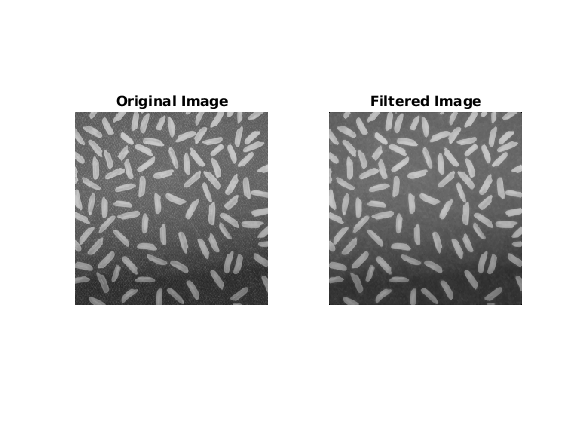

img = imread('rice.png');
imSmoothed = medfilt2(img, [3 3]);
subplot(1,2,1),imshow(img),title("Original Image");
subplot(1,2,2),imshow(imSmoothed),title("Filtered Image");

### User defined functions for Median

%READ AN 2D IMAGE
A=imread('rice.png'); % coins.png pout.tif rice.png
% figure,imshow(A),title('IMAGE WITH SALT AND PEPPER NOISE');
%PAD THE MATRIX WITH ZEROS ON ALL SIDES
modifyA=zeros(size(A)+2);
B=zeros(size(A));
%COPY THE ORIGINAL IMAGE MATRIX TO THE PADDED MATRIX
for x=1:size(A,1)
    for y=1:size(A,2)
        modifyA(x+1,y+1)=A(x,y);
    end
end


%LET THE WINDOW BE AN ARRAY
%STORE THE 3-by-3 NEIGHBOUR VALUES IN THE ARRAY
%SORT AND FIND THE MIDDLE ELEMENT
for i= 1:size(modifyA,1)-2
    for j=1:size(modifyA,2)-2
        window=zeros(9,1);
        inc=1;
        for x=1:3
            for y=1:3
                window(inc)=modifyA(i+x-1,j+y-1);
                inc=inc+1;
            end
        end
        med=sort(window);
        %PLACE THE MEDIAN ELEMENT IN THE OUTPUT MATRIX
        B(i,j)=med(5);
    end
end

%CONVERT THE OUTPUT MATRIX TO 0-255 RANGE IMAGE TYPE
B=uint8(B);

%subplot
subplot(1,2,1),imshow(A),title("Original Image");
subplot(1,2,2),imshow(B),title("Filtered Image");

### Pre-defined functions for Mean

I = imread('rice.png');
H = fspecial('average', 3);
I2 = imfilter( I, H );
subplot(1,2,1),imshow(I),title("Original Image");
subplot(1,2,2),imshow(I2),title("Filtered Image");

### User defined functions Mean

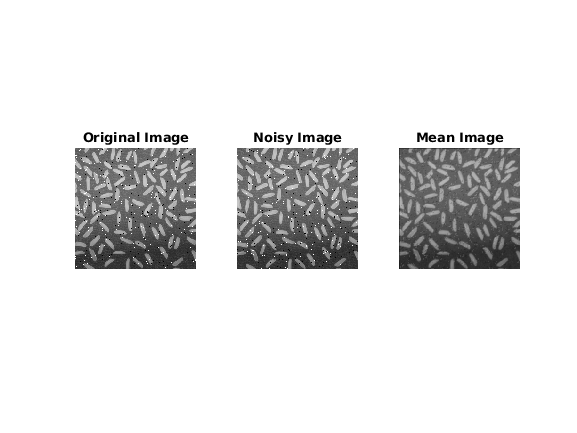

clc;
clear;
close all;
img = imread('rice.png');
imgn = imnoise(img, 'salt & pepper', 0.02);
img = padarray(imgn,[1,1]);
[m,n] = size(img);
for i=2:(m-1)
    for j=2:(n-1)
        v = [img(i-1,j-1),img(i-1,j),img(i-1,j+1),img(i,j-1),img(i,j),img(i,j+1),img(i+1,j-1),img(i+1,j),img(i+1,+1)];
        new = mean(v);
        new_img(i,j) = uint8(ceil(new));
    end
end
subplot(1,3,1),imshow(img),title("Original Image");
subplot(1,3,2),imshow(imgn),title("Noisy Image");
subplot(1,3,3),imshow(new_img),title("Mean Image");

### user defined max function

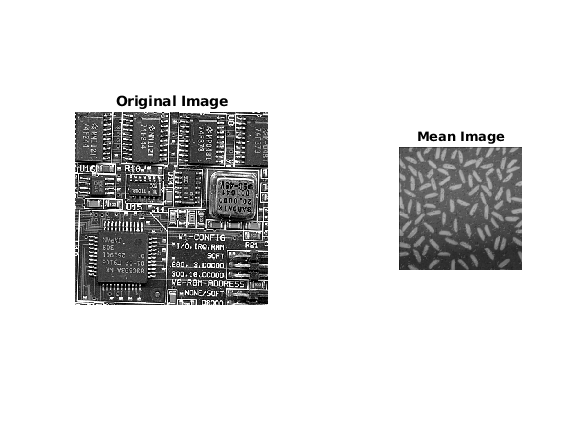

%READ AN IMAGE
A = imread('board.tif');
A = rgb2gray(A(1:300,1:300,:));
%PREALLOCATE THE OUTPUT MATRIX
B=zeros(size(A));
%PAD THE MATRIX A WITH ZEROS
modifyA=padarray(A,[1 1]);
x=[1:3]';
y=[1:3]';
for i= 1:size(modifyA,1)-2
    for j=1:size(modifyA,2)-2
        %VECTORIZED METHOD
        window=reshape(modifyA(i+x-1,j+y-1),[],1);
        %FIND THE MAXIMUM VALUE IN THE SELECTED WINDOW
        B(i,j)=max(window);
    end
end

%CONVERT THE OUTPUT MATRIX TO 0-255 RANGE IMAGE TYPE
B=uint8(B);
subplot(1,2,1),imshow(A),title("Original Image");

subplot(1,2,2),imshow(B),title("Max Filtered ");

### user defined min function

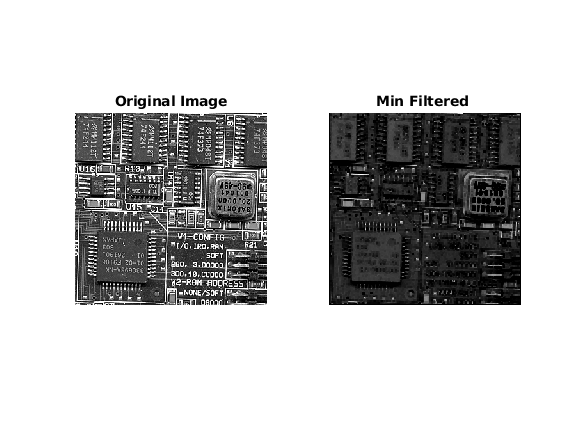

%READ AN IMAGE
A = imread('board.tif');
A = rgb2gray(A(1:300,1:300,:));
%PREALLOCATE THE OUTPUT MATRIX
B=zeros(size(A));
%PAD THE MATRIX A WITH ZEROS
modifyA=padarray(A,[1 1]);
x=[1:3]';
y=[1:3]';
for i= 1:size(modifyA,1)-2
    for j=1:size(modifyA,2)-2
        %VECTORIZED METHOD
        window=reshape(modifyA(i+x-1,j+y-1),[],1);
        %FIND THE MINIMUM VALUE IN THE SELECTED WINDOW
        B(i,j)=min(window);
    end
end

%CONVERT THE OUTPUT MATRIX TO 0-255 RANGE IMAGE TYPE
B=uint8(B);
subplot(1,2,1),imshow(A),title("Original Image");
subplot(1,2,2),imshow(B),title("Min Filtered ");